# AutoDRIVE Ecosystem | Nigel - Tire Stiffness Validation

clear;
close;
clc;

% Environment parameters

u_fl = 0.4; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.4; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.4; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.4; % Coefficient of friction for ground and RR tire interconnect

% Vehicle parameters

m = 2.68; % Mass [kg]
J = 0.01944; % Yaw moment of inertia [kg-m^2]
l = 0.1415; % Wheelbase [m]
w = 0.1530; % Track width [m]
l_f = 0.5*l; % Distance from CG to front axel [m]
l_r = l-l_f; % Distance from CG to rear axel [m]
C_fl = 2.4768; % Cornering stiffness of FL tire [N/rad]
C_fr = 2.4768; % Cornering stiffness of FR tire [N/rad]
C_rl = 2.4768; % Cornering stiffness of RL tire [N/rad]
C_rr = 2.4768; % Cornering stiffness of RR tire [N/rad]

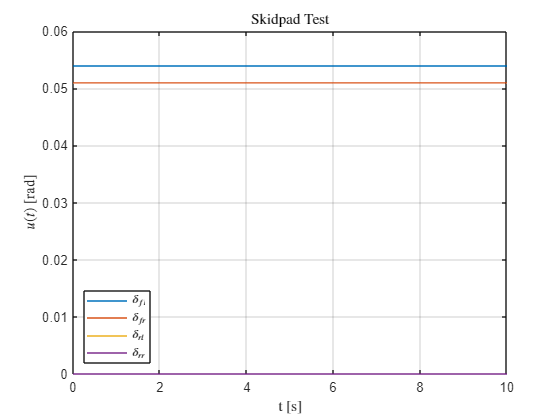

% Maneuver parameters

v = 0.35; % Vehicle velocity [m/s]
delta = ones(1,10000)*(deg2rad(0.1*30));
u1_skidpad = atan2((2*l*tan(delta)),((2*l)-(w*tan(delta))));
u2_skidpad = atan2((2*l*tan(delta)),((2*l)+(w*tan(delta))));
u3_skidpad = zeros(1,10000);
u4_skidpad = zeros(1,10000);
u_skidpad = [u1_skidpad; u2_skidpad; u3_skidpad; u4_skidpad];

% Plot
t=1:10000;
figure();
plot(t/1000,u1_skidpad)
hold on;
plot(t/1000,u2_skidpad)
plot(t/1000,u3_skidpad)
plot(t/1000,u4_skidpad)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','southwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Skidpad Test','Interpreter','latex')
grid on;
hold off;

% Vehicle model

a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));

b11 = (u_fl*C_fl)/(m*v);
b12 = (u_fr*C_fr)/(m*v);
b13 = (u_rl*C_rl)/(m*v);
b14 = (u_rr*C_rr)/(m*v);
b21 = (l_f*u_fl*C_fl)/J;
b22 = (l_f*u_fr*C_fr)/J;
b23 = -(l_r*u_rl*C_rl)/J;
b24 = -(l_r*u_rr*C_rr)/J;

A = [a11 a12;
     a21 a22];

B = [b11 b12 b13 b14;
     b21 b22 b23 b24];

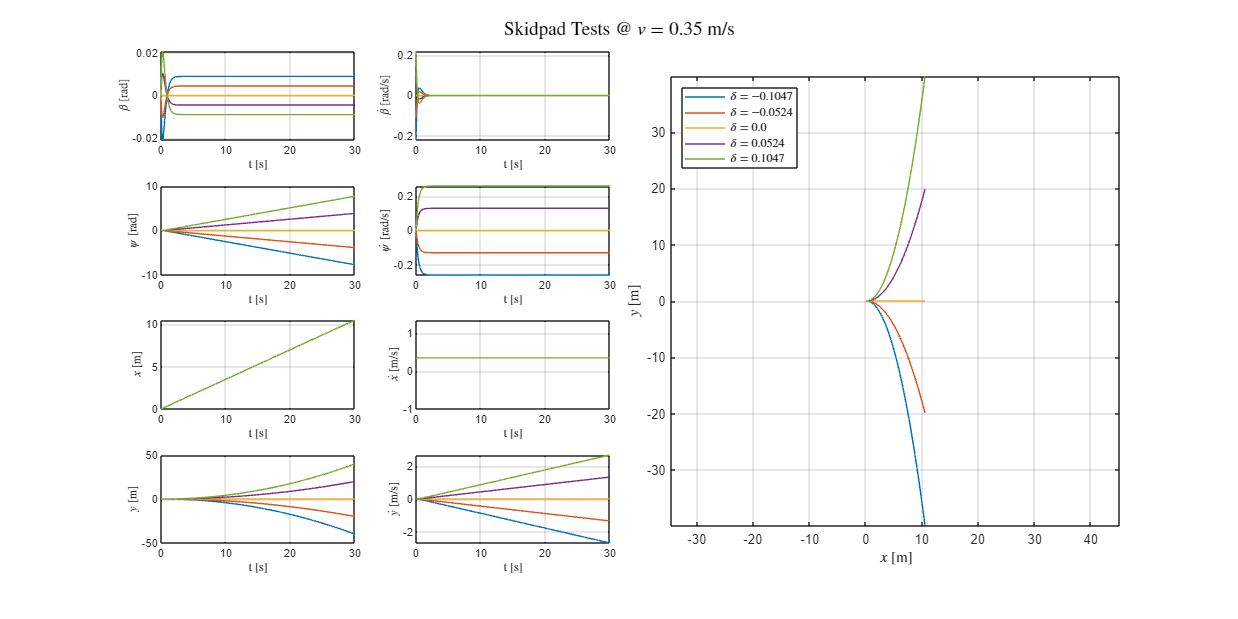

% Simulate skidpad tests with varying steering

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PSI_DDOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for i=-0.2:0.1:0.2
    % Control inputs
    delta = ones(1,30000)*(deg2rad(i*30));
    u1_skidpad = atan2((2*l*tan(delta)),((2*l)-(w*tan(delta))));
    u2_skidpad = atan2((2*l*tan(delta)),((2*l)+(w*tan(delta))));
    u3_skidpad = zeros(1,30000);
    u4_skidpad = zeros(1,30000);
    u_skidpad = [u1_skidpad; u2_skidpad; u3_skidpad; u4_skidpad];
    
    % Initialization
    dt = 0.001; % Simulation timestep [s]
    u = 0.4; % Coefficient of friction
    v = 0.35; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;
    
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    
    % Update input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
     b21 b22 b23 b24];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t)+B*u_skidpad(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v;
        Vy(t) = v*(Psi(t)+Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PSI_DDOT(end+1,:) = X_dot(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
axis equal
pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Skidpad Tests @ $v = 0.35$ m/s','Interpreter','latex')
legend('$\delta = -0.1047$','$\delta = -0.0524$','$\delta = 0.0$','$\delta = 0.0524$','$\delta = 0.1047$', ...
       'Interpreter','latex','Location','northwest')

% Downsample data for steady state region

idx = 15000;
beta = BETA(:,idx);
psi = PSI(:,idx);
psi_dot = PSI_DOT(:,idx);
psi_ddot = PSI_DDOT(:,idx);
vx = VX(:,idx);
vy = VY(:,idx);
delta = -0.2:0.1:0.2;
delta = deg2rad(delta*30)';

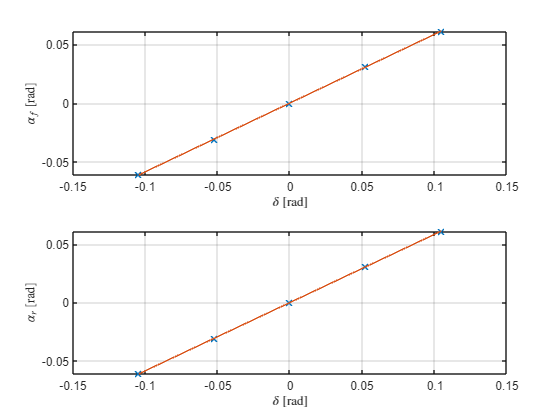

% Tire slip angle estimation

beta = vy./vx - psi;
alpha_f = -beta-(l_f.*psi_dot./vx)+delta;
alpha_r = -beta+(l_r.*psi_dot./vx);

delta_alpha_f = polyfix(delta,alpha_f,1,0,0);
delta_alpha_r = polyfix(delta,alpha_r,1,0,0);

figure()
subplot(2,1,1)
plot(delta,alpha_f,'x',LineWidth=1)
hold on
plot(delta,polyval(delta_alpha_f,delta))
xlabel('$\delta$ [rad]','Interpreter','latex')
ylabel('$\alpha_f$ [rad]','Interpreter','latex')
grid('on')
subplot(2,1,2)
plot(delta,alpha_r,'x',LineWidth=1)
hold on
plot(delta,polyval(delta_alpha_r,delta))
xlabel('$\delta$ [rad]','Interpreter','latex')
ylabel('$\alpha_r$ [rad]','Interpreter','latex')
grid('on')

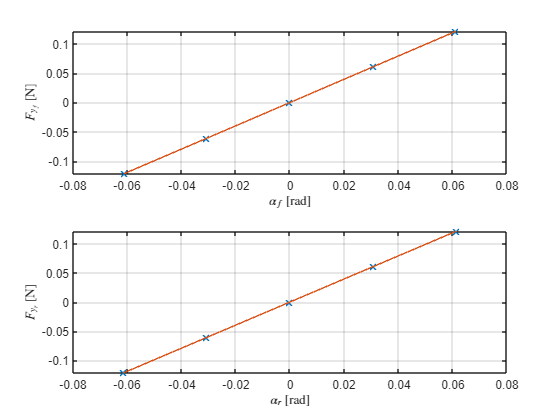

% Tire stiffness estimation

a_y = vx.*psi_dot;
Fy_f = (m.*a_y.*l_r + J*psi_ddot)./(l);
Fy_r = (m.*a_y.*l_f - J*psi_ddot)./(l);

org = ceil(length(alpha_f)/2);

force_alpha_f = polyfix(alpha_f(org-1:org+1),Fy_f(org-1:org+1),1,0,0);
force_alpha_r = polyfix(alpha_r(org-1:org+1),Fy_r(org-1:org+1),1,0,0);

figure()
subplot(2,1,1)
plot(alpha_f,Fy_f,'x',LineWidth=1)
hold on
plot(alpha_f,polyval(force_alpha_f,alpha_f))
xlabel('$\alpha_f$ [rad]','Interpreter','latex')
ylabel('$F_{y_f}$ [N]','Interpreter','latex')
grid('on')
subplot(2,1,2)
plot(alpha_r,Fy_r,'x',LineWidth=1)
hold on
plot(alpha_r,polyval(force_alpha_r,alpha_r))
xlabel('$\alpha_r$ [rad]','Interpreter','latex')
ylabel('$F_{y_r}$ [N]','Interpreter','latex')
grid('on')

result = sprintf('Tire Stiffness: %.4f N/rad', (force_alpha_f(1)+force_alpha_r(1))/2);
disp(result);

Tire Cornering Stiffness: 1.9828 N/rad
